%Define LIM Parameters (Parallel to ANSYS rmXprt LinearMCore definition)
WIDTH_CORE = 800; %Core width in motion direction
THICK_CORE = 100; %Core thickness
LENGTH = 50; %Core length
GAP = 6; %Gap between core and xy plane (or 1/2 of air gap)
SLOT_PITCH = 30; %Distance between two slots
SLOTS = 24; %Number of slots
Hs0 = 0; %Slot opening height
Hs01 = 0; %Slot closed bridge height
Hs1 = 0; %Slot wedge height
Hs2 = 60; %Slot body height (Height of teeth gap)
Bs0 = 20; %Slot opening width
Bs1 = 20; %Slot wedge maximum Width
Bs2 = 10; %Slot body bottom width
Rs = 0; %Slot body bottom fillet
Layers = 2; %Number of winding layers
coil_pitch = 2; %Coil Pitch measured in slots
end_ext = 20; %One-sided winding end extended length
SPAN_EXT = 20; %Core endlength
SEG_ANGLE = 15; %Deviation angle for slot arches

%Simulation Flags
SAVE_BITMAP = false;
RUN_SIM = true;

%Define Simulation Default Parameters
inputCurrent = 10;
freq = 15;
coilTurns = 310;
trackThickness = 8;
copperMaterial = '20 AWG';
trackMaterial = 'Aluminum, 6061-T6';
coreMaterial = 'M-19 Steel';

%Define Simulation Specific Parameters
sumSlotTeeth = SLOTS*2+1; %Number of Teeth + Slots
slotGap = SLOT_PITCH-Bs1; %Width of an Individual Slot
slotTeethWidth = (SLOTS-1)*SLOT_PITCH+slotGap;
coilArea = slotGap*Hs2/2; %Area of coil for a single phase

%Update rules for LIM core parameters
SLOT_PITCH=(WIDTH_CORE)/SLOTS

SLOT_PITCH = 33.3333

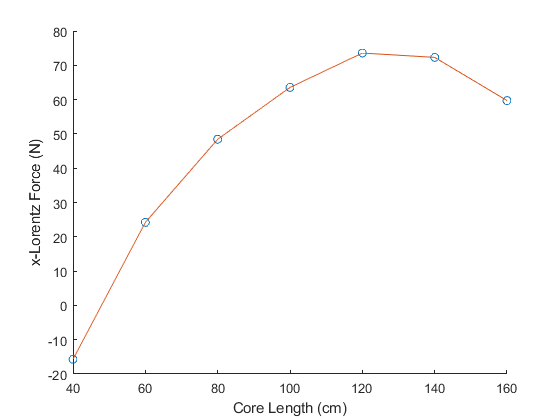


[losses,totalLosses,lforcex,lforcey,wstforcex,wstforcey,vA,vB,vC,cA,cB,cC,flA,flB,flC] = run_simulation(inputCurrent,freq,coilTurns,trackThickness,copperMaterial,coreMaterial,trackMaterial,WIDTH_CORE,THICK_CORE,LENGTH,GAP,SLOT_PITCH,SLOTS,Hs0,Hs01,Hs1,Hs2,Bs0,Bs1,Bs2,Rs,Layers,coil_pitch,end_ext,SAVE_BITMAP,RUN_SIM);


% Test for 450 - 900 mm, with plot 
lforceplot = zeros(1,7);
corelengthplot = (40:20:160);

for i = 0:6
    WIDTH_CORE = 400 + i*200;
    SLOT_PITCH=(WIDTH_CORE)/SLOTS;
    [losses,totalLosses,lforcex,lforcey,wstforcex,wstforcey,vA,vB,vC,cA,cB,cC,flA,flB,flC] = run_simulation(inputCurrent,freq,coilTurns,trackThickness,copperMaterial,coreMaterial,trackMaterial,WIDTH_CORE,THICK_CORE,LENGTH,GAP,SLOT_PITCH,SLOTS,Hs0,Hs01,Hs1,Hs2,Bs0,Bs1,Bs2,Rs,Layers,coil_pitch,end_ext,SAVE_BITMAP,RUN_SIM);
    lforceplot(i + 1) = lforcex;
end

figure
scatter(corelengthplot, lforceplot);

hold on 

plot(corelengthplot, lforceplot);
xlabel("Core Length (cm)");
ylabel("x-Lorentz Force (N)");